# Explainable AI for Medical Images 

In this example, we show how to use MATLAB to produce post-hoc explanations (using [Grad-CAM](https://www.mathworks.com/help/deeplearning/ref/gradcam.html) and [image LIME](https://www.mathworks.com/help/deeplearning/ref/imagelime.html)) for a medical image classification task, defined as follows: 

**Given a chest x-ray (CXR), our solution should **[**classify it into Posteroanterior (PA) or Lateral (L) view**](https://doi.org/10.1016/j.media.2020.101797)**.  **

The dataset (PadChest) can be downloaded from [https://bimcv.cipf.es/bimcv-projects/padchest/](https://bimcv.cipf.es/bimcv-projects/padchest/) .

Both methods ([`gradCAM`](matlab:doc('gradCAM')) and [`imageLIME`](matlab:doc('imageLIME'))) are available as part of the MATLAB Deep Learning toolbox and require a single line of code to be applied to results of predictions made by a deep neural network (plus a few lines of code to display the results as a colormap overlaid on the actual images).

### Load training data

% Please adjust the path below, if needed
dataFolder = './sample_rgb';

imdsTrain = imageDatastore(dataFolder, ...
    'IncludeSubfolders',true, ....
    'LabelSource','foldernames');

numTrainingFiles = 0.7;
[imdsTrain,imdsValidation] = splitEachLabel(imdsTrain,numTrainingFiles);

rng(42); % Random number generator seed (to ensure reproducibility)


### Display example images

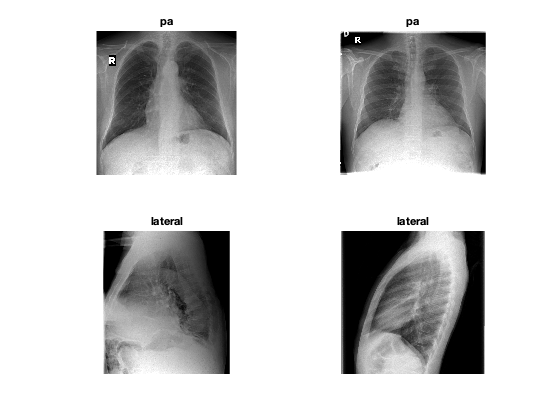

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I), title(imdsTrain.Labels(idx(i)))
end

### Define network and data augmentation options

imageAugmenter = imageDataAugmenter( ...
    'RandXTranslation',[-3 3], ...
'RandYTranslation',[-3 3]);
net = squeezenet;
layers = layerGraph(net);
inputSize = net.Layers(1).InputSize;
numClasses = numel(categories(imdsTrain.Labels));

imdsTrainAug = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation', imageAugmenter);
imdsValidationAug = augmentedImageDatastore(inputSize(1:2), ...
    imdsValidation);

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
layers = replaceLayer(layers,'pool10',newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
layers = replaceLayer(layers,'ClassificationLayer_predictions',newClassLayer);

### Specify training options

options = trainingOptions('rmsprop', ...
    'MiniBatchSize',21, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidationAug, ...
    'ValidationFrequency',30, ...
    'Verbose',true, ...
    'Plots', "training-progress");


### Train network

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       76.92% |       40.00% |       3.6790 |       9.5654 |          0.0010 |
|      30 |          30 |       00:00:50 |       84.62% |       80.00% |       1.3188 |       3.1885 |          0.0010 |
|======================================================================================================================|


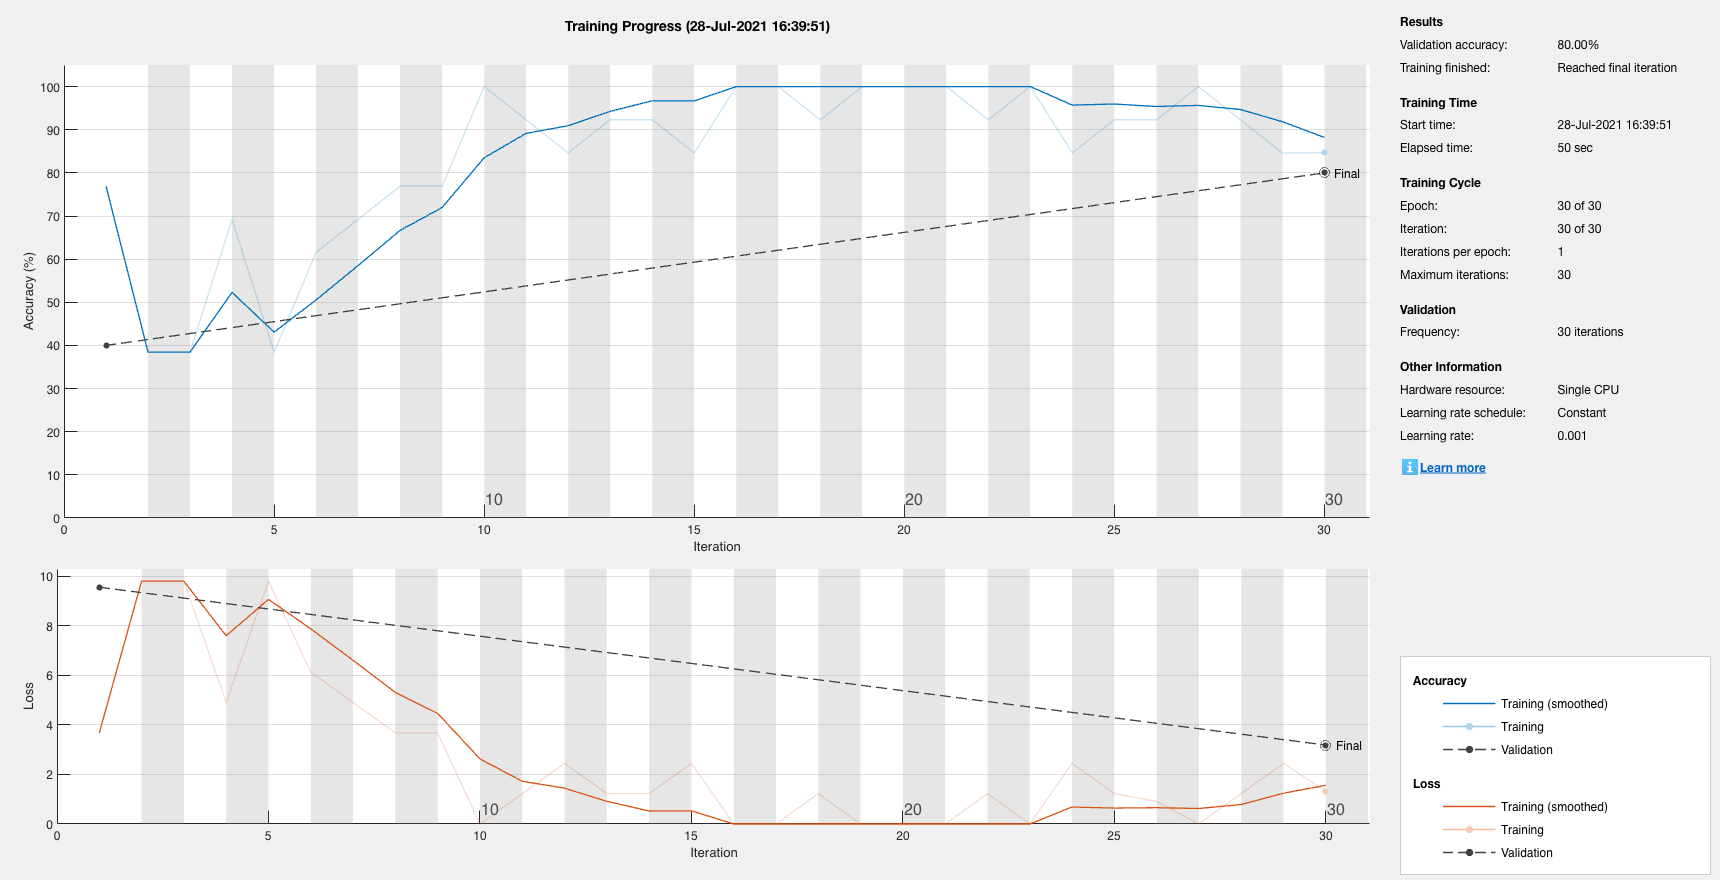

netTransfer = trainNetwork(imdsTrainAug,layers,options);

### Classify validation Images

Classify the validation images using the fine-tuned network.

[YPred,scores] = classify(netTransfer,imdsValidationAug);
YValidation = imdsValidation.Labels;

Display four sample validation images with their predicted labels.

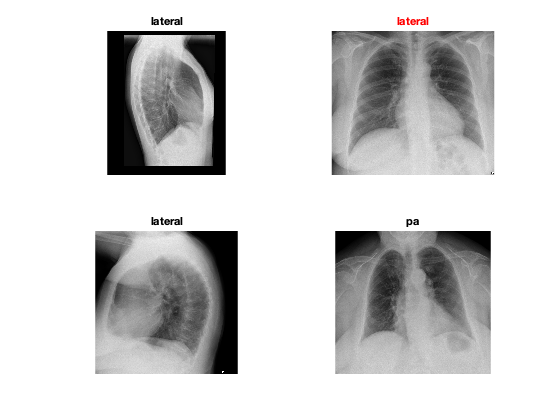

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
end

Calculate the classification accuracy on the validation set. Accuracy is the fraction of labels that the network predicts correctly.

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.8000

### Explain predictions

#### Using `gradCAM`

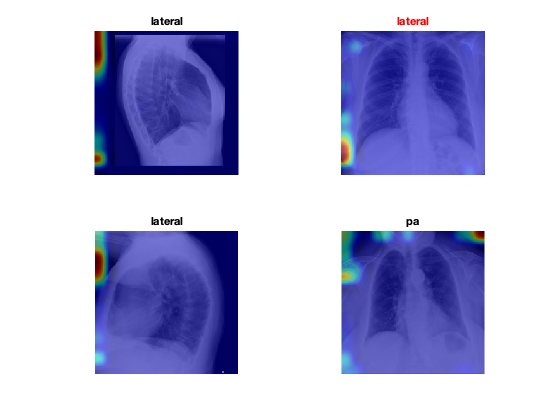

figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    I_resized = imresize(I,net.Layers(1).InputSize(1:2));
    label = YPred(idx(i));
    scoreMap = gradCAM(netTransfer,I_resized,label);
    imshow(I_resized)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
    hold off
end

#### Using `imageLIME`

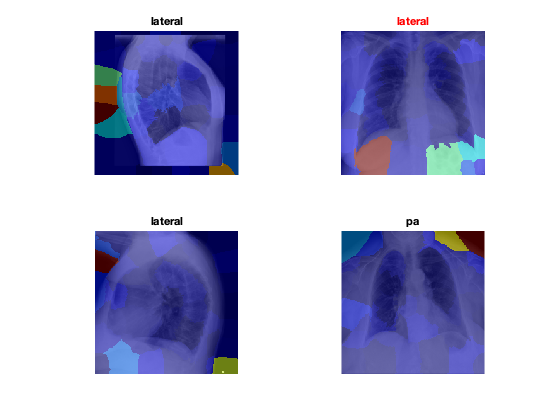

figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    I_resized = imresize(I,net.Layers(1).InputSize(1:2));
    label = YPred(idx(i));
    scoreMap = imageLIME(netTransfer,I_resized,label);
    imshow(I_resized)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    % colorbar
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
    hold off
end